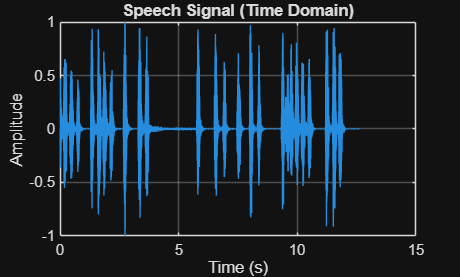

clc; clear; close all;
%% 1) SAMPLING — Load or record speech
[filename, pathname] = uigetfile('dog.wav');
[x, Fs] = audioread(fullfile(pathname, filename));
% Use only one channel if stereo
if size(x,2) > 1
    x = x(:,1);
end
N = length(x);
t = (0:N-1) / Fs;   % time vector
figure;
plot(t, x);
xlabel('Time (s)'); ylabel('Amplitude');
title('Speech Signal (Time Domain)');
grid on;

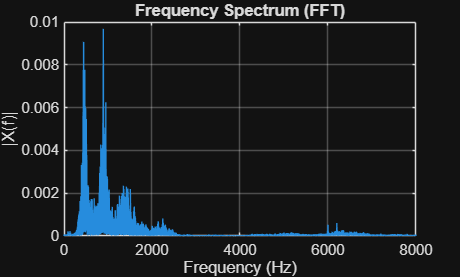

%% 2) FFT — Frequency Spectrum
X = fft(x);
X_mag = abs(X(1:floor(N/2)+1));      % single-sided magnitude
X_mag = X_mag / N;                    % normalize
X_mag(2:end-1) = 2*X_mag(2:end-1);    % account for folded energy
f = (0:floor(N/2)) * Fs / N;          % frequency axis
figure;
plot(f, X_mag);
xlabel('Frequency (Hz)'); ylabel('|X(f)|');
title('Frequency Spectrum (FFT)');
grid on;

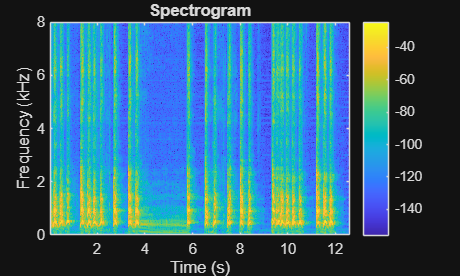

%% 3) SPECTROGRAM — Time-Frequency Representation
figure;
windowLength = round(0.03 * Fs);   % 30 ms window
overlap = round(0.02 * Fs);        % 20 ms overlap
nfft = 1024;
spectrogram(x, hamming(windowLength), overlap, nfft, Fs, 'yaxis');
title('Spectrogram');
colorbar;

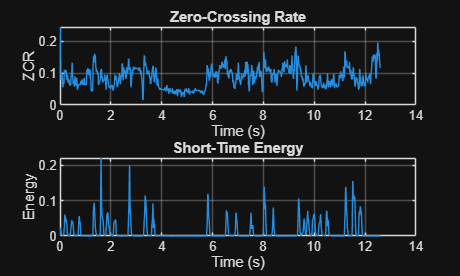

%% ================================================================
%  OPTIONAL FEATURES
% ================================================================
%% 4) Zero-Crossing Rate (ZCR) — frame-based
frameSize = round(0.025 * Fs);   % 25 ms
frameShift = round(0.010 * Fs);  % 10 ms
numFrames = floor((N - frameSize) / frameShift) + 1;
zcr = zeros(numFrames,1);
energy = zeros(numFrames,1);
for i = 1:numFrames
    startIdx = (i-1)*frameShift + 1;
    endIdx = startIdx + frameSize - 1;
    frame = x(startIdx:endIdx);
    % --- Zero-crossing rate ---
    zcr(i) = sum(abs(diff(sign(frame)))) / (2*frameSize);
    % --- Short-time energy ---
    energy(i) = sum(frame.^2) / frameSize;
end

frameTimes = ((0:numFrames-1)*frameShift + frameSize/2) / Fs;
figure;
subplot(2,1,1);
plot(frameTimes, zcr);
xlabel('Time (s)'); ylabel('ZCR');
title('Zero-Crossing Rate');
grid on;

subplot(2,1,2);
plot(frameTimes, energy);
xlabel('Time (s)'); ylabel('Energy');
title('Short-Time Energy');
grid on;

%% ================================================================
%  DONE
% ================================================================
disp('Analysis complete.');

Analysis complete.
